# Projeto de sistemas de Controle

## Boas práticas

clear all;                              % Apaga variáveis
clc;                                    % limpa a tela
close all;                              % fecha todas as janelas


## Importando dados

[Omega,Theta,Entrada] = ImportaDados('exp7.txt',1, 4685);

%%% Especificando o tempo

Ts    = 1e-3;                       % taxa de amostargem - 1ms
tempo = linspace(0,4685*Ts,4685);   % vetor tempo para análise dos sinais


## Visualizando dados

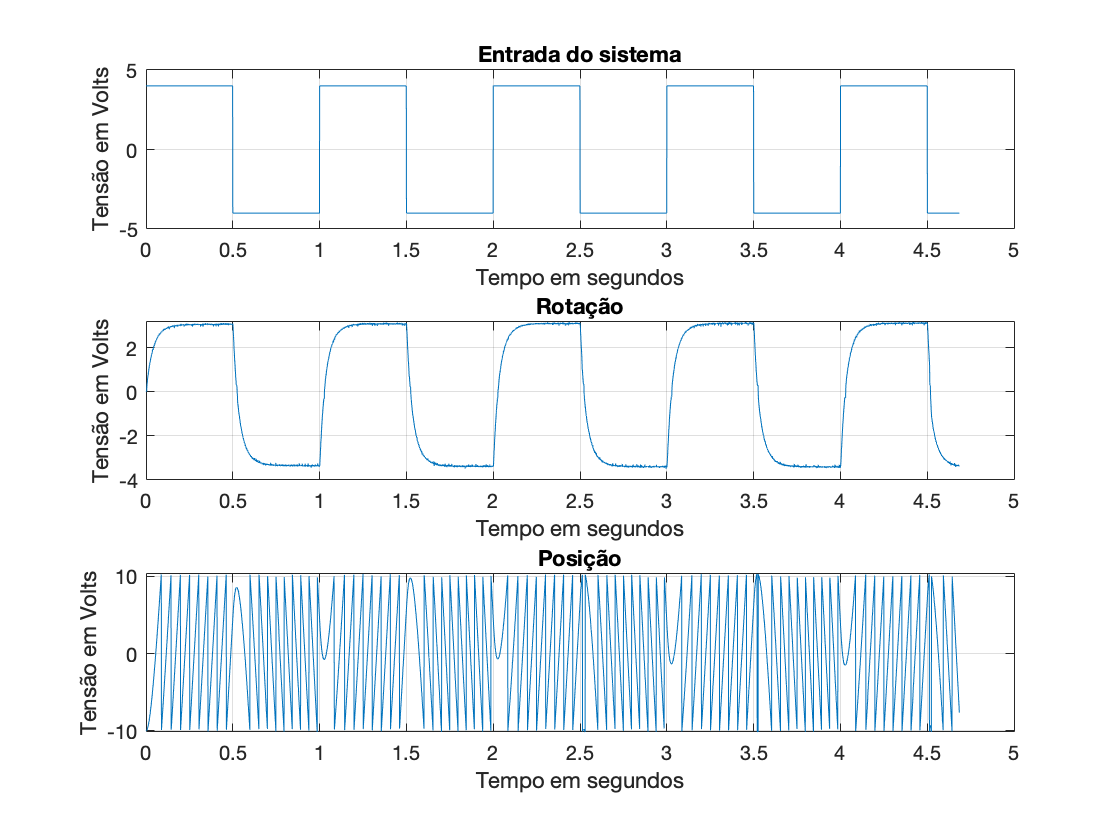

figure(1)

subplot(3,1,1)
plot(tempo,Entrada);
title('Entrada do sistema');
ylabel('Tensão em Volts');
xlabel('Tempo em segundos');
grid;

subplot(3,1,2)
plot(tempo,Omega);
title('Rotação');
ylabel('Tensão em Volts');
xlabel('Tempo em segundos');
grid;

subplot(3,1,3)
plot(tempo,Theta);
title('Posição');
ylabel('Tensão em Volts');
xlabel('Tempo em segundos');
grid;

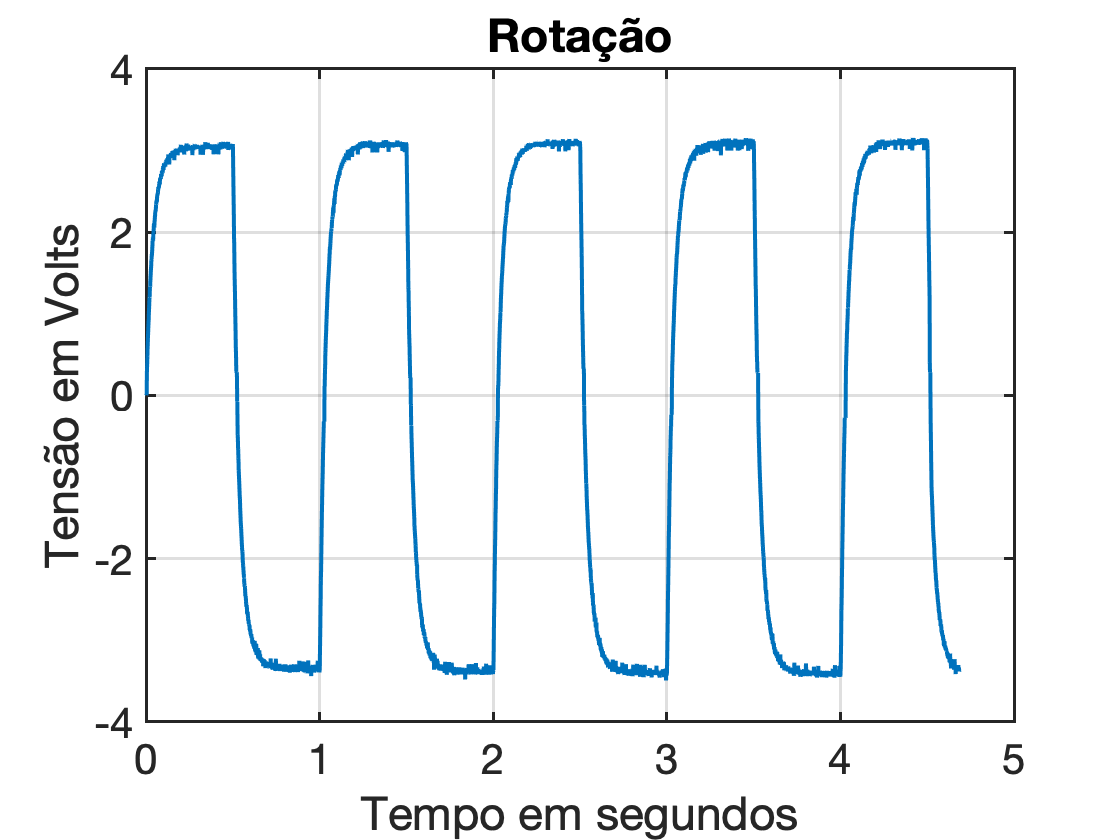



figure()

plot(tempo,Omega);
title('Rotação');
ylabel('Tensão em Volts');
xlabel('Tempo em segundos');
grid;

 set(findall(gcf,'Type','line'),'LineWidth',2);
 set(gca,'FontSize',21,'LineWidth',1.5);

## Análise dos sinais no domínio de Laplace

O sinal de entrada $U(s)$ foi aplicado a um sistema cuja função de transferência gerou o sinal $\Omega(s)$. Logo a relação entre entrada e saída é dada pela função de transferência:

$\frac{\Omega(s)}{U(s)} =  \frac{K_m}{s+p_m}$ . Neste caso supomos ser de primera ordem pelo aspecto geral do sinal **Rotação**.

Gp = tf(1,[1 1])

Gp =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



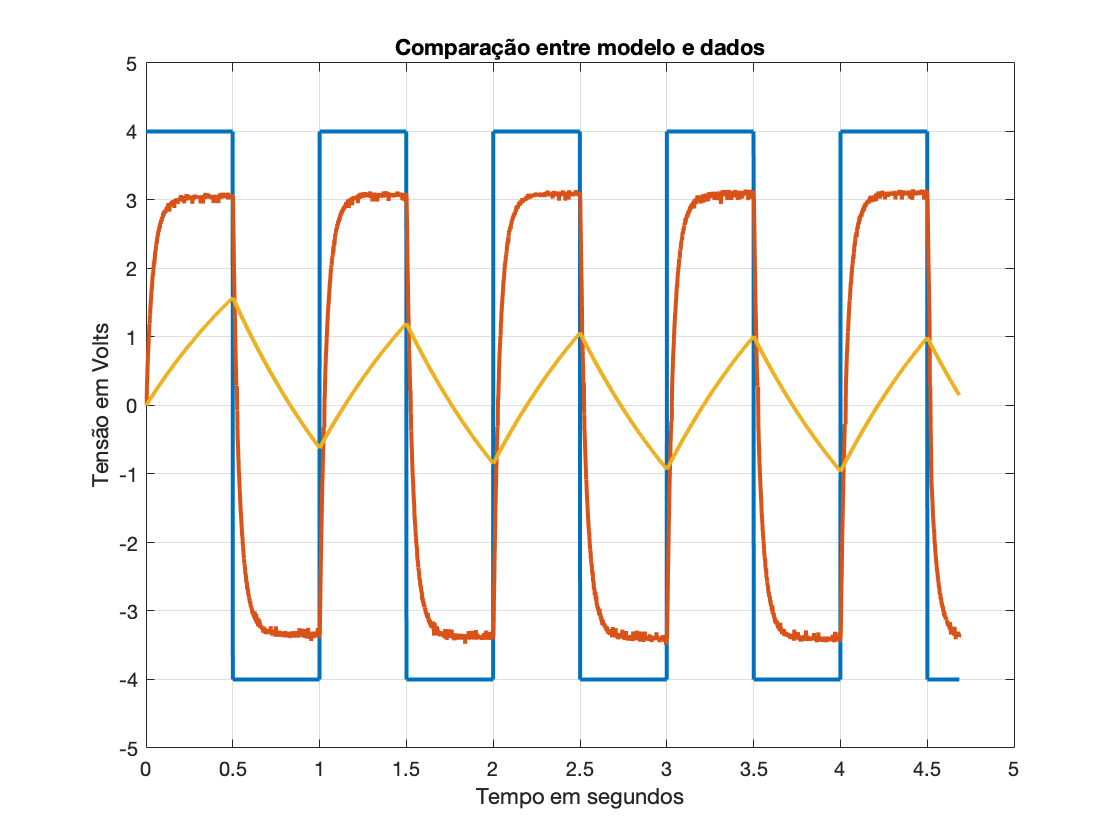


ym = lsim(Gp,Entrada,tempo);
figure(2)
plot(tempo,Entrada, tempo,Omega, tempo,ym, "LineWidth",2);
axis([0 5 -5 5]);
title('Comparação entre modelo e dados');
ylabel('Tensão em Volts');
xlabel('Tempo em segundos');
grid;

## Ajustando os parâmetros do modelo

x0 = [1 1]

x0 =      1     1



X = fminsearch(@(x) ErroQuadratico(x,Entrada,Omega,tempo') ,x0) 

X =    22.4732   28.0882


## Verificando o resultado

Gp = tf(X(1),[1 X(2)])

Gp =
 
    22.47
  ---------
  s + 28.09
 
Continuous-time transfer function.



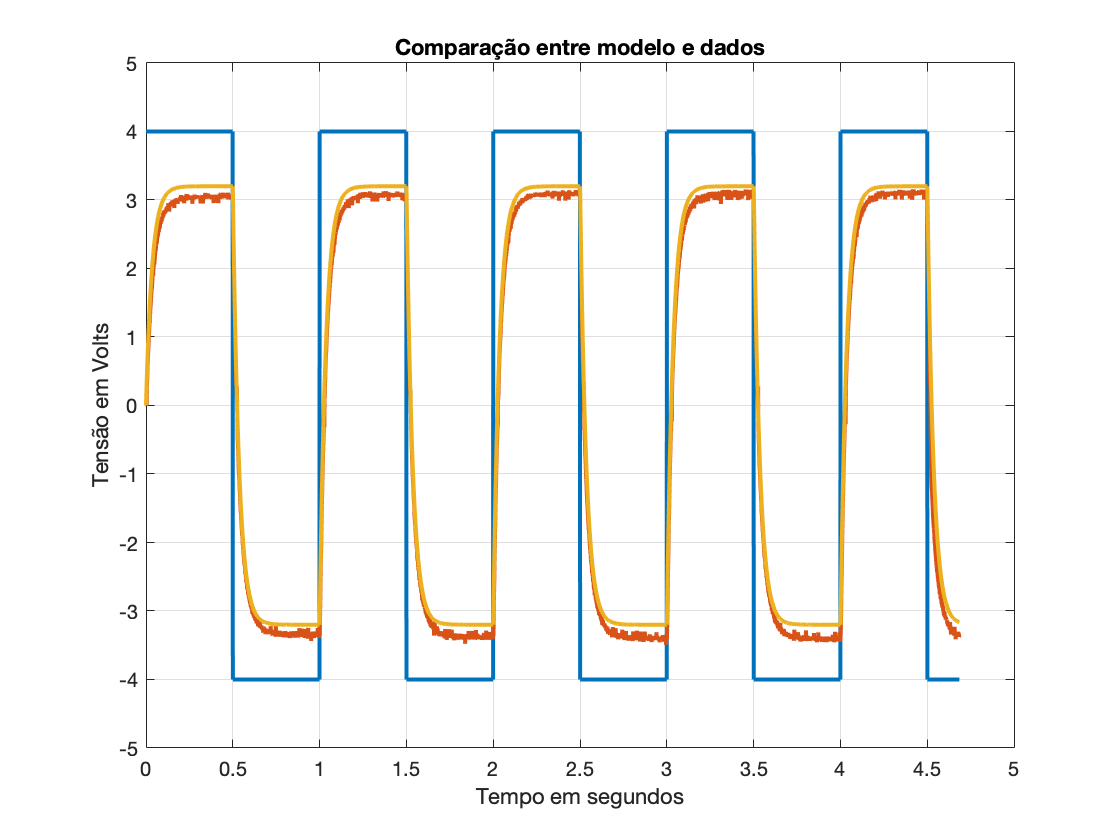


ym = lsim(Gp,Entrada,tempo);
figure(2)
plot(tempo,Entrada, tempo,Omega, tempo,ym, "LineWidth",2);
axis([0 5 -5 5]);
title('Comparação entre modelo e dados');
ylabel('Tensão em Volts');
xlabel('Tempo em segundos');
grid;

## Sintonizando um controlador proporcional

                %%% Estimando o tempo de acomodação 
                %%% Obtendo o polo da função de tranferência
                
                den  = Gp.Denominator;         % resulta em um array do tipo cell
                
                den  = cell2mat(den);        % converte para manipulação direta
                
                polo = roots(den);             % determina as raizes
                
                Ts   =  4/polo(1);             % estimativa a partir do critério de 2%
                
                %%% Determinando o tempo de acomodação critério de 2%
                %%% abordagem computacional
                
                %%% Extraindo um dos trechos dos dados
                
                ti = max(find(tempo<0.5));
                
                t1 = tempo(1:ti);
                y1 = Omega(1:ti);
                
                %%% Estima o valor final da saída real
                
                Vf  =  mean(y1(end-50:end));
                
                Ti = min(find(y1>0.98*Vf))

Ti = 163

                Ts = t1(Ti)

Ts = 0.1620

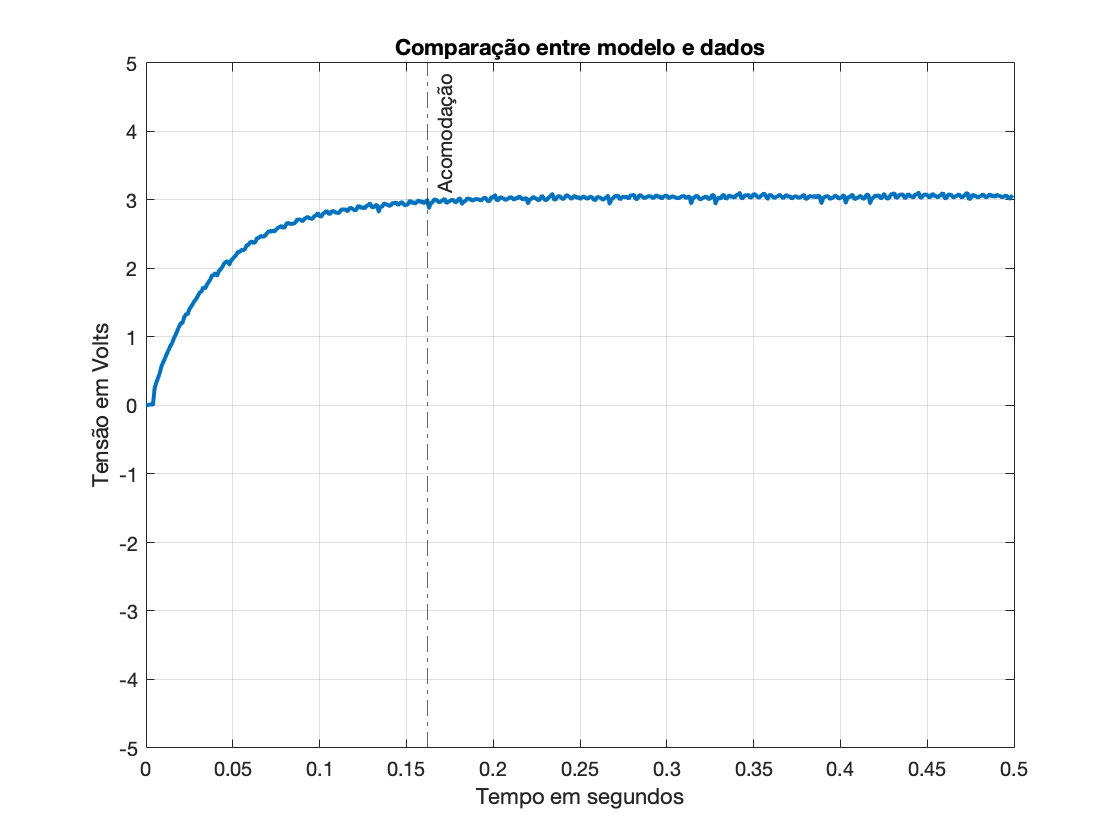

                figure(3)
                plot(t1,y1, "LineWidth",2);
                axis([0 0.5 -5 5]);
                title('Comparação entre modelo e dados');
                ylabel('Tensão em Volts');
                xlabel('Tempo em segundos');
                grid;
                xline(Ts,'-.','Acomodação')

## Controle para modificação o tempo de acomodação

Tsd  =  0.1;        % tempo de acomodação desejado

%%% estima o polo em malha fechada

pmf  =  4/Tsd;      

%%% podemos criar um modelo de referência (desejado)

Kmf  = pmf;
Gr   =  tf(Kmf,[1 pmf])

Gr =
 
    40
  ------
  s + 40
 
Continuous-time transfer function.



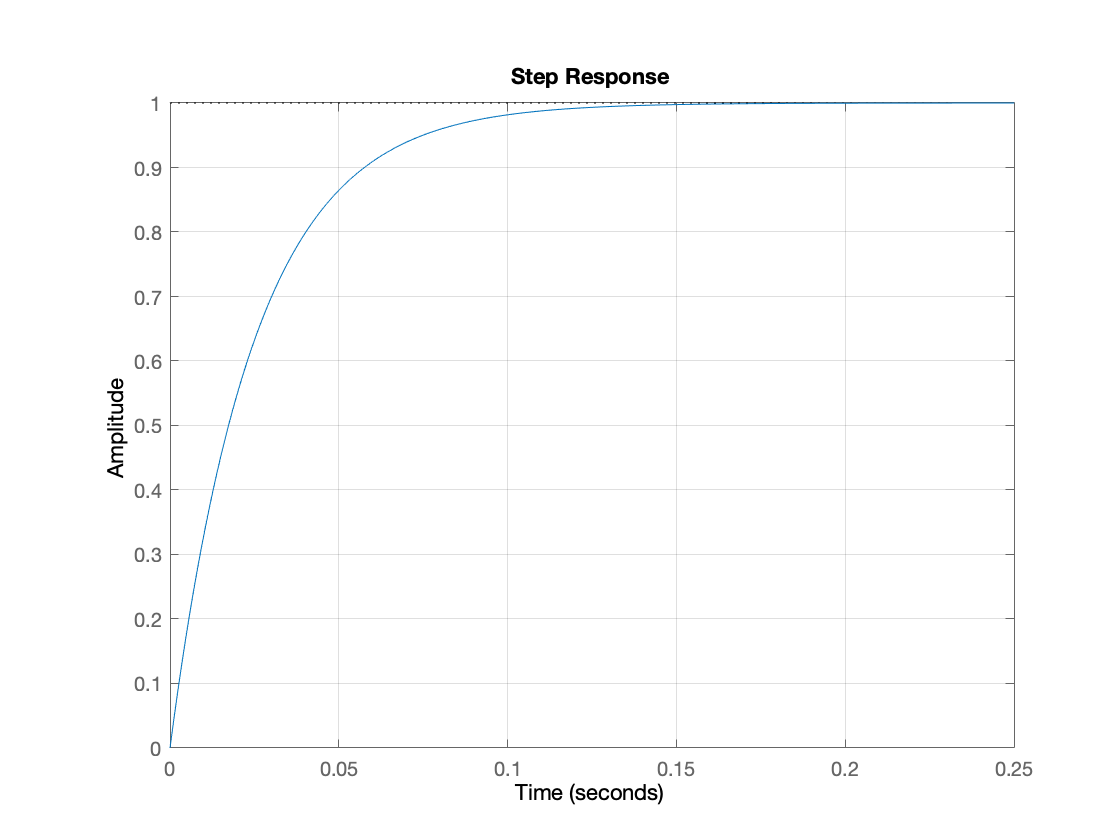


figure(4)

step(Gr); grid;

## Analisando o ganho de controlador

K  = [0.1 0.5 1 1.5 2 3 4 5 6 7 8 9];

step(Gr); 
grid;
hold;

Current plot held



for k=1:10
     Gmf = feedback(tf(K(k)*X(1),[1 X(2)]),1);
     step(Gmf)
end

## Analisando o erro estacionário

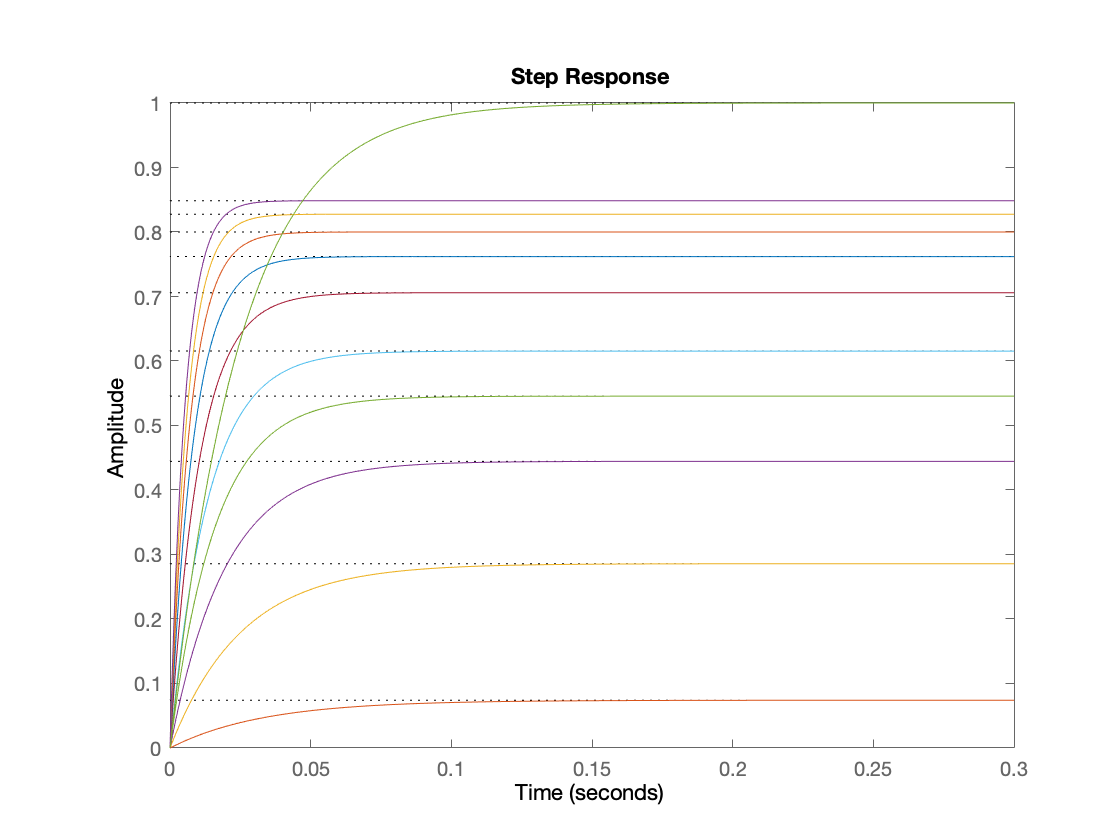

Current plot released


K  = [0.1 0.5 1 1.5 2 3 4 5 6 7 8 9];

step(Gr); 
grid;
hold;

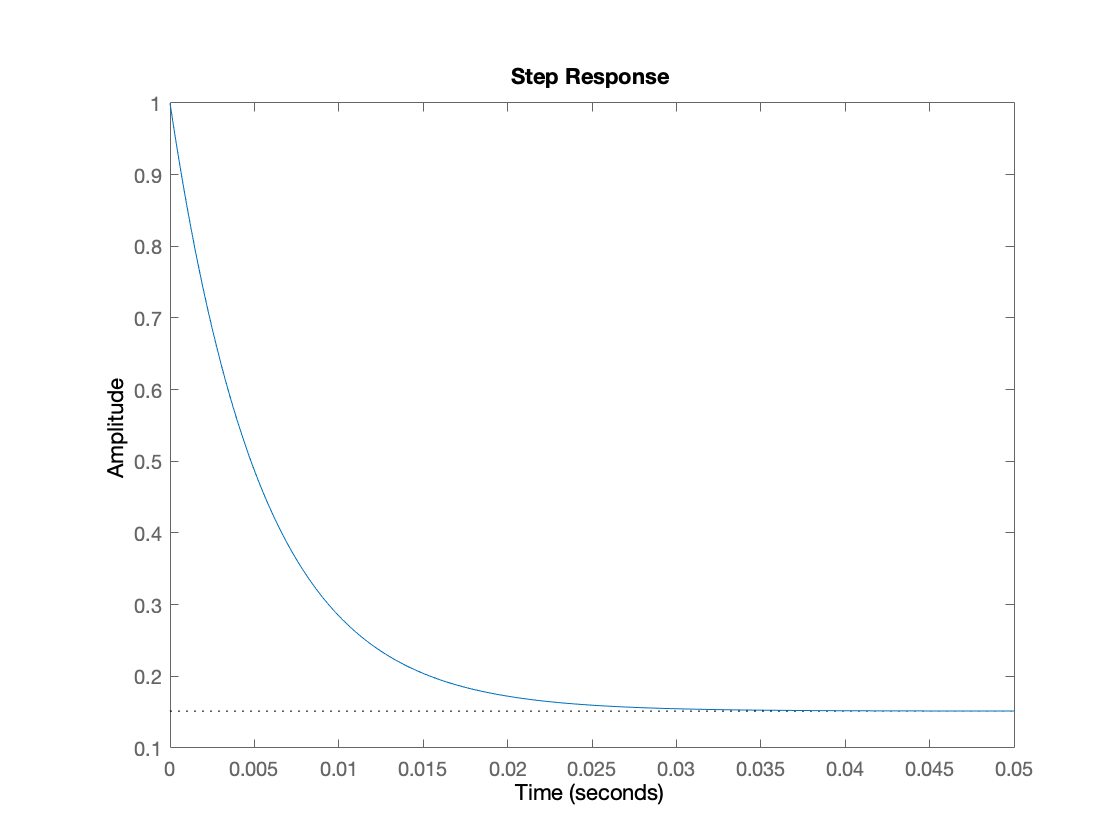


for k=1:10
     Gmf = feedback(1,tf(K(k)*X(1),[1 X(2)]));
     step(Gmf)
 end

## Analisando o esforço de controle

K  = [0.1 0.5 1 1.5 2 3 4 5 6 7 8 9];

step(Gr); 
grid;
hold;

Current plot held


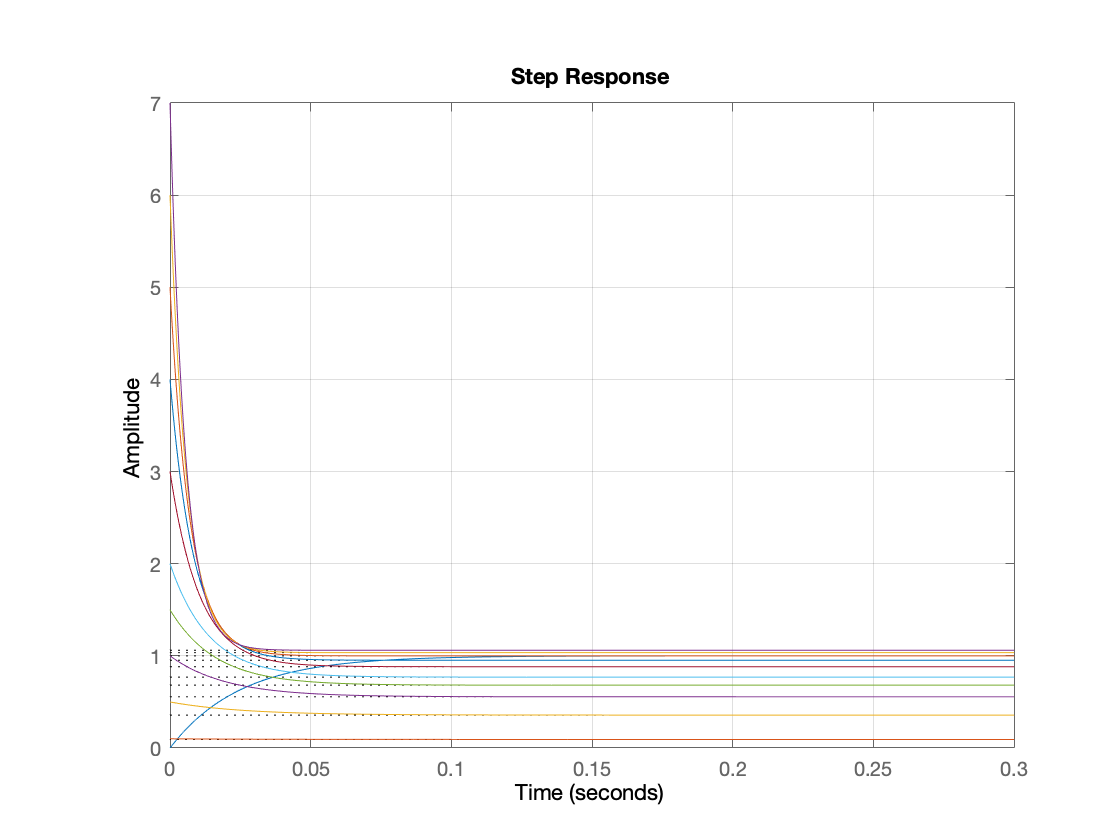


for k=1:10
     Gmf = feedback(K(k),tf(X(1),[1 X(2)]));
     step(Gmf)
 end